**预处理阶段的操作如下**：

首先，基于 `Utils.export_selected_basins` ，借助 TopoToolBox 对研究区的 DEM 数据开展流域分析。分析完成后，所有得到的流域将会展示在一个 figure 上。

接着，可以通过鼠标左键来选择一个或者多个感兴趣的流域，在完成选择操作后，按下 Enter 键，便能结束选择流程，且所选流域会被导出至 output_workspace 文件夹下。

而在 output_workspace 文件夹下，输出的格式按照如下方式进行组织：

- basins_id_list：其为选中的流域的 id 列表，有助于后续开展自动化处理；

- basins \ 

-     basin_{流域ID} \

-         basin_{流域ID}.tif

完成预处理操作后，即可通过 `GeomorphicIndicesExtractApp.mlapp` 进行多流域的地貌指数计算。

其中，地貌指数的 `Input_workspace` 可以选中此处的 `Output_workspace` ，而地貌指数的 `Output_workspace` 可以选择想要放置结果的位置。

流域 70 导出到 assets\test\TaiHang\result\basins\basin_70\basin_70.tif
流域 18 导出到 assets\test\TaiHang\result\basins\basin_18\basin_18.tif
流域 27 导出到 assets\test\TaiHang\result\basins\basin_27\basin_27.tif
流域 2 导出到 assets\test\TaiHang\result\basins\basin_2\basin_2.tif


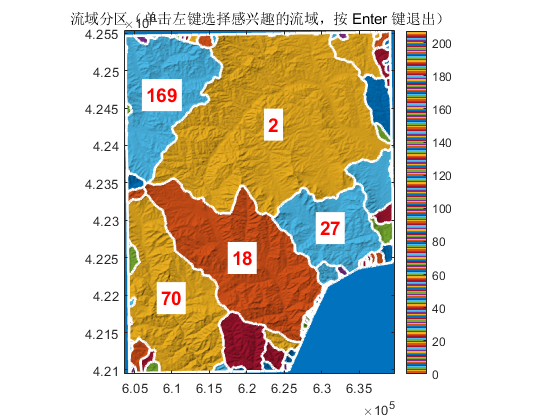

流域 169 导出到 assets\test\TaiHang\result\basins\basin_169\basin_169.tif
流域导出完成！


clear;
clc;

dem_file_path = "assets\test\TaiHang\TaiHang.tif";
output_workspace = "assets\test\TaiHang\result\";

Utils.export_selected_basins(dem_file_path, output_workspace);

导出完成后可以在此处自动打开 `GeomorphicIndicesExtractApp.mlapp，也可以自行运行。在此处自动打开则输入输出工作空间自动填充为此处的 output_workspace。`

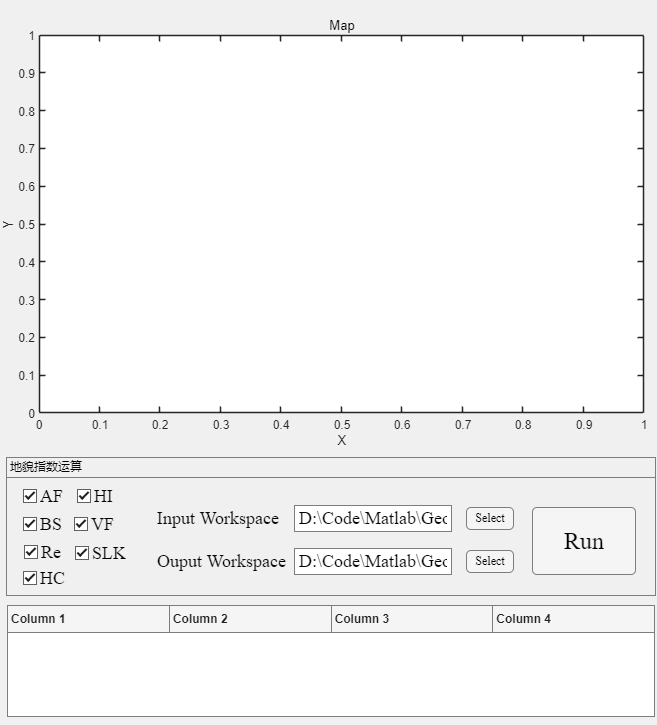

GeomorphicIndicesExtractApp 已打开！


% 弹窗询问是否打开应用程序
choice = questdlg('是否打开 GeomorphicIndicesExtractApp.mlapp？', ...
                  '打开应用程序', ...
                  '是', '否', '否'); % 设置按钮选项

% 根据用户选择执行操作
if strcmp(choice, '是')
    % 打开应用程序
    app = GeomorphicIndicesExtractApp();
    workspace = fullfile(pwd, output_workspace);

    % 填充应用程序的文本框
    app.OutputFolderText.Value = workspace;
    app.SelectedFileText.Value = workspace;
    
    disp("GeomorphicIndicesExtractApp 已打开！");
else
    disp("操作已取消。");
end